# ***M. capsulatus***** cocultures study**

**Loyal Murphy - August 25, 2024**

Using this code, I'll be able to apply the Gompertz model to each system and be able to use the final values.

### **Initialization**

clear variables
clc
clf

# **DATA EXTRACTION**

### Extract Coculture OD Data

scans = dir('*.mat');

all_coc_OD = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if contains(n,'OD') && (startsWith(n,'C') || startsWith(n,'F') || startsWith(n,'L'))
        ms = ms + 1;
        cOD_data = load(n);
        if length(fieldnames(cOD_data)) == 3
            j = fieldnames(cOD_data);
            data = cOD_data.(j{1});
            factor = cOD_data.(j{2});
            to = cOD_data.(j{3});
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                odValues(x) = data{x,1}.Abs(data{x,1}.nm == 750);
            end
            all_coc_OD{ms,1} = reshape(odValues,[size(data,1)/3,3]).*factor';
                            
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_coc_OD{ms,2} = time_matrix;

        elseif length(fieldnames(cOD_data)) == 2
            j = fieldnames(cOD_data);
            
            %Get the OD values (factor already multiplied)
            all_coc_OD{ms,1} = cOD_data.(j{1});
            
            %Get the time values (initial time already subtracted)
            all_coc_OD{ms,2} = cOD_data.(j{2});
        end

    clear data factor to odValues j k x cOD_data pts
    end
end
clear n ms time_matrix i

%Make all the data consistent
all_coc_OD{4,2} = transpose(all_coc_OD{4,2});


### Extract Coculture gDCW data

scans = dir('*.mat');

all_coc_gDCW = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if contains(n,'gDCW') && (startsWith(n,'C') || startsWith(n,'F') || startsWith(n,'L'))
        ms = ms + 1;
        cDW_data = load(n);
        if length(fieldnames(cDW_data)) == 3
            j = fieldnames(cDW_data);
            data = cDW_data.(j{1});
            factor = cDW_data.(j{2});
            to = cDW_data.(j{3});
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                gDCWValues(x) = data{x,1}.Abs(data{x,1}.nm == 750);
            end
            all_coc_gDCW{ms,1} = reshape(gDCWValues,[size(data,1)/3,3]).*factor';
            all_coc_gDCW{ms,1} = transpose(all_coc_gDCW{ms,1});
                            
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_coc_gDCW{ms,2} = time_matrix;
            all_coc_gDCW{ms,2} = transpose(all_coc_gDCW{ms,2})

        elseif length(fieldnames(cDW_data)) == 2
            j = fieldnames(cDW_data);
            
            %Get the OD values (factor already multiplied)
            all_coc_gDCW{ms,1} = cDW_data.(j{1});
            all_coc_gDCW{ms,1} = transpose(all_coc_gDCW{ms,1});
            
            %Get the time values (initial time already subtracted)
            all_coc_gDCW{ms,2} = cDW_data.(j{2});
            all_coc_gDCW{ms,2} = transpose(all_coc_gDCW{ms,2});
        end

    clear data factor to gDCWValues j k x cDW_data pts
    end
end
clear n ms time_matrix i 

%Orient the data so it matches the others (Biomass, then time)
tempCell = all_coc_gDCW;
all_coc_gDCW(:,1) = tempCell(:,2);
for k = 1:size(all_coc_gDCW,1)
    all_coc_gDCW{k,1} = all_coc_gDCW{k,1}*1000 - 0.345;
end
all_coc_gDCW(:,2) = tempCell(:,1);
%Remove scan data to keep workspace clean
clear scans tempCell k

### Adjust the gDCW data for each coculture

Coc_titles = ["Cap + Dim (37)";"Cap + Dim (30)";"Cap + Soro (30)";"Cap + Soro (37)"];
Xo_calc = [0.040,0.040,0.031,0.031];
coc_gDCW = cell(4,2);

for i = 1:4
    OD_Times = all_coc_OD{i,2};
    OD_data = all_coc_OD{i,1};
    gDCW_Times = all_coc_gDCW{i,2};
    gDCW_data = all_coc_gDCW{i,1};

    %Find time that gDCW exceeds 0.5gDCW/L
    t_switch = min(gDCW_Times(mean(gDCW_data,2) > 0.5));

    %Get ODo, Xo, ODt, and Xt where t = tswitch for linear proportions.
    ODave = mean(OD_data,2);
    Xave = mean(gDCW_data,2);
    
    ODo = ODave(1);
    Xo = Xo_calc(i);
    ODt = ODave(OD_Times == t_switch);
    Xt = Xave(gDCW_Times == t_switch);
    OD_idx = find(~(OD_Times-t_switch));
    gDCW_idx = find(~(gDCW_Times-t_switch));

    %Transform the OD values into gDCW values and look at the linearity.
    OD_vals = [];
    OD_t = [];
    gDCW_vals = [];
    gDCW_t = [];
    for j = [1,OD_idx,OD_idx+1]
        OD_vals = [OD_vals,OD_data(j,:)];
        OD_t = [OD_t,OD_Times(j)*[1,1,1]];
    end

    gDCW_vals = Xo*[1,1,1];
    for k = [gDCW_idx,gDCW_idx+1]
        gDCW_vals = [gDCW_vals,gDCW_data(k,:)];
    end

    % Fit the data to a linear fit
    f3 = fit(OD_vals',gDCW_vals','poly1');
    new_gDCW = f3.p1*OD_data(1:sum(OD_Times < t_switch-1),:) + f3.p2;
    
    %Transform OD values into gDCW values at t < t_switch
    %new_gDCW = Xo + ((OD_data(1:sum(OD_Times < t_switch-1),:)-ODo)/(ODt-ODo))*(Xt - Xo);
    
    %Now make new data!
    coc_gDCW{i,1} = [new_gDCW;gDCW_data(sum(gDCW_Times < t_switch-1)+1:end,:)];
    if i == 4 %vertcat error with OD times
        coc_gDCW{i,2} = [OD_Times(OD_Times < t_switch - 1)';gDCW_Times(gDCW_Times > t_switch - 1)];
    else
        coc_gDCW{i,2} = [OD_Times(OD_Times < t_switch - 1);gDCW_Times(gDCW_Times > t_switch - 1)];
    end
end

### Analysis

Coc_titles = ["Cap + Dim (37)";"Cap + Dim (30)";"Cap + Soro (30)";"Cap + Soro (37)"];
Inits = {[1.5,0.10,20],[4,0.15,10],[2.7,0.15,10],[2.5,0.2,10]}; %Initials for Gompertz solver
Inits2 = {[0.1,1],[0.15,1],[0.15,1],[0.15,1],}; %Initials for exponential solver

% Make storage variables for later %
K_vals = zeros(3,length(Coc_titles));
D_vals = zeros(3,length(Coc_titles));
muR_vals = zeros(3,length(Coc_titles));
tLAG_vals = zeros(3,length(Coc_titles));
mu_max_vals = zeros(3,length(Coc_titles));
mu_max_vals3 = zeros(3,length(Coc_titles));
mu_max_vals4 = zeros(3,length(Coc_titles));
mu_max_vals5 = zeros(3,length(Coc_titles));
td_vals = zeros(3,length(Coc_titles));
td_vals4 = zeros(3,length(Coc_titles));
td_vals5 = zeros(3,length(Coc_titles));

for i = 1:size(coc_gDCW,1)
    gDCWs = coc_gDCW{i,1};
    Times = coc_gDCW{i,2};
   
    % Plot the individual data sets with their Gompertz models
    for j = 1:3
        % Set up fitting parameters %

        foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0.025],'Upper',[5.0,0.3,35,0.05],'StartPoint',[Inits{i},0.025]);
        ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
        % a = Carrying Capacity
        % b = Growth Rate
        % c = Delay Time
        % d = Vertical Shift

        % Define gDCW measurements and model predictions
        x = Times;
        y = gDCWs(:,j);

        if i == 2
            x = x(1:end-1);
            y = y(1:end-1);
        end

        [curve_ZMB,~] = fit(x,y,ft_ZMB);
        K_vals(j,i) = curve_ZMB.a;
        muR_vals(j,i) = curve_ZMB.b;
        tLAG_vals(j,i) = curve_ZMB.c;
        D_vals(j,i) = curve_ZMB.d;

        % Lastly, try using the piecewise model from 0 to Tlag
        tEXP5 = linspace(0,tLAG_vals(j,i),50);
        fo5 = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0],'Upper',[0.2,0.3,30],'StartPoint',[Xo,Inits2{i}]);
        ft_XMXo5 = fittype('expo(t,x1,x2,x3)','independent',{'t'},'options',fo5);
        [curve_XMXo5,sXMXo5] = fit(tEXP5',curve_ZMB(tEXP5),ft_XMXo5);
        mu_max_vals5(j,i) = curve_XMXo5.x2;
        td_vals5(j,i) = curve_XMXo5.x3;

    end

end 

### Plotting Coculture gDCW data

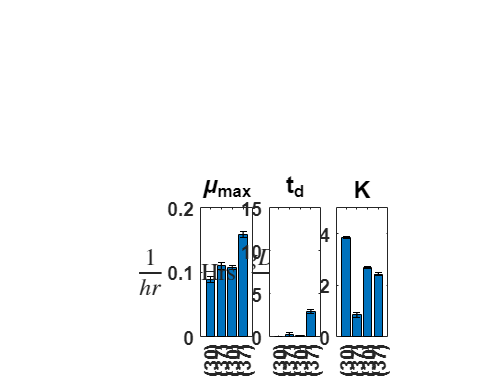

% Reorder code %%%%%%%%%%%%%%%%%%%
while ~strcmp(Coc_titles(1),'Cap + Dim (30)') %Ensures reordering happens only once!
pub_idx = [2 1 3 4];
Coc_titles = Coc_titles(pub_idx);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

f456 = figure(456); clf;
subplot(2,6,11)
hold on
statgDCW_val = mean(K_vals)'+ mean(D_vals)';
statgDCW_std = std(K_vals)';
bar(categorical(Coc_titles),statgDCW_val(pub_idx));
errorbar(statgDCW_val(pub_idx),statgDCW_std(pub_idx)','LineStyle','none','Color','k','LineWidth',1);
hold off
set(gca,'FontSize',16,'FontWeight','bold');
ylabel('$\frac{gDCW}{L}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,5]);
title('K','FontSize',20,'FontWeight','bold');
box on;

subplot(2,6,9)
hold on
max_ave = mean(mu_max_vals5);
max_std = std(mu_max_vals5);
b = bar(categorical(Coc_titles),max_ave(pub_idx));
eb = errorbar(max_ave(pub_idx),max_std(pub_idx),'LineStyle','none','Color','k','LineWidth',1);
hold off
set(gca,'FontSize',16,'FontWeight','bold');
title('\mu_{max}','FontSize',20,'FontWeight','bold')
ylabel('$\frac{1}{hr}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,0.20]);
box on;

subplot(2,6,10)
hold on
td_ave = mean(td_vals5);
td_std = std(td_vals5);
bb = bar(categorical(Coc_titles),td_ave(pub_idx));
ebeb = errorbar(td_ave(pub_idx),td_std(pub_idx),'LineStyle','none','Color','k','LineWidth',1);
hold off
set(gca,'FontSize',16,'FontWeight','bold');
title('t_d','FontSize',20,'FontWeight','bold')
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,15]);
box on;

## Coculture Average  Models

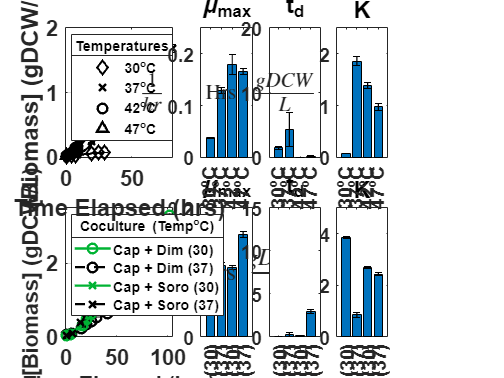

Coc_titles = ["Cap + Dim (37)";"Cap + Dim (30)";"Cap + Soro (30)";"Cap + Soro (37)"];
Colors = {[0 0 0],[0 0.7 0.2],[0 0.7 0.2],[0 0 0]};
Marks = ["o","o","x","x"];
Styles = {'--','-','-','--'};
Inits = {[4.4,0.1,2],[2.4,0.1,2],[1.4,0.1,20],[4.2,0.1,1],[1.4,0.1,1],[2.3,0.1,1]}; %Initials for solver!

%figure(); clf; %Start a new plot
subplot(2,3,4);
figSpace = cell(4,1);
%All the code below is to plot the Gompertz fits onto monoculture data
for i = 1:4
    gDCWs = coc_gDCW{i,1};
    Times = coc_gDCW{i,2}; 
    xAve = mean(gDCWs,2);
    xstd = std(gDCWs,[],2);

    if i == 2 %Cap + Dim (30)
       Times = Times(1:end-1);
       xAve = xAve(1:end-1);
       xstd = xstd(1:end-1);
    end

    Xo = Xo_calc(i); %Initial biomass
    foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,Xo*0.8],'Upper',[6,0.3,25,Xo*1.2],'StartPoint',[Inits{i},Xo]);
    ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
    
    [curve_ZMB,sZMB] = fit(Times,xAve,ft_ZMB);
    tSpace = linspace(0,max(Times),301);

    %Plot the Data, Error Bars, and Model in order.
    hold on
    plot(Times,xAve,'Marker',Marks(i),'Color',Colors{i},'MarkerSize',8,'LineStyle','none','LineWidth',2);
    errorbar(Times,xAve,xstd,'k','LineStyle','none');
    plot(tSpace,curve_ZMB(tSpace),'LineStyle',Styles{i},'Color',Colors{i},'LineWidth',2)
    p = plot(nan,'Marker',Marks(i),'Color',Colors{i},'MarkerSize',8,'LineStyle',Styles{i},'LineWidth',2);
    figSpace{i} = p;
    hold off
end
ax = gca;
ax.FontSize = 18;
ax.FontWeight = 'bold';
xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold');
ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
lgd = legend([figSpace{2},figSpace{1},figSpace{3},figSpace{4}],{"Cap + Dim (30)","Cap + Dim (37)","Cap + Soro (30)","Cap + Soro (37)"}, ...
    'FontSize',12,'location','northwest');
title(lgd,'Coculture (Temp^{o}C)');
ax.YGrid = 'on';
axis([0 105 0 3.5])
box(ax,'on');
ax_set = ax;

load fab.mat;
load fc.mat;
load fd.mat;
load fe.mat;

subplot(2,3,1,copyobj(aab,f456));
lgd = legend('30^{o}C','','','37^{o}C','','','42^{o}C','','','47^{o}C','','','FontSize',12,'location','northwest');
title(lgd,'Temperatures');
subplot(2,6,3,copyobj(ac,f456));
ax = gca;
ax.FontSize = 16;
ax.FontWeight = 'bold';
ax.YAxis.FontSize = 18;
ax.Title.FontSize = 20;
subplot(2,6,4,copyobj(ad,f456));
ax = gca;
ax.FontSize = 16;
ax.FontWeight = 'bold';
ax.YAxis.FontSize = 18;
ax.Title.FontSize = 20;
subplot(2,6,5,copyobj(ae,f456));
ax = gca;
ax.FontSize = 16;
ax.FontWeight = 'bold';
ax.YAxis.FontSize = 18;
ax.Title.FontSize = 20;